%ref: https://www.mathworks.com/help/wlan/ug/image-transmission-reception-using-802-11-waveform-sdr.html?searchHighlight=image%20transmission&s_tid=srchtitle_support_results_3_image%20transmission
%needs to install WLAN Toolbox

sdrdevice = "ad9361" %"pluto" %ad9361

sdrdevice = "ad9361"

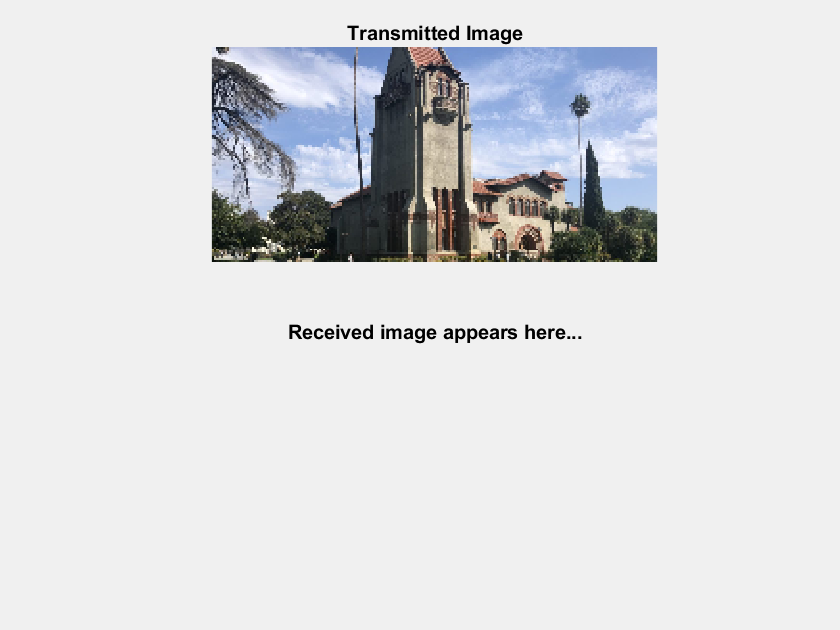


% Setup handle for image plot
if ~exist('imFig','var') || ~ishandle(imFig) %#ok<SUSENS> 
    imFig = figure;
    imFig.NumberTitle = 'off';
    imFig.Name = 'Image Plot';
    imFig.Visible = 'off';
else
    clf(imFig); % Clear figure
    imFig.Visible = 'off';
end

% Setup Spectrum viewer
spectrumScope = spectrumAnalyzer( ...
    SpectrumType='power-density', ...
    Title='Received Baseband WLAN Signal Spectrum', ...
    YLabel='Power spectral density', ...
    Position=[69 376 800 450]);

% Setup the constellation diagram viewer for equalized WLAN symbols
refQAM = wlanReferenceSymbols('64QAM');
constellation = comm.ConstellationDiagram(...
    Title='Equalized WLAN Symbols',...
    ShowReferenceConstellation=true,...
    ReferenceConstellation=refQAM,...
    Position=[878 376 460 460]);

% Input an image file and convert to binary stream
fileTx = 'sjsu.jpg';                   % Image file name
fData = imread(fileTx);                          % Read image data from file
scale = 0.2;                    % Image scaling factor
origSize = size(fData);                          % Original input image size
scaledSize = max(floor(scale.*origSize(1:2)),1); % Calculate new image size
heightIx = min(round(((1:scaledSize(1))-0.5)./scale+0.5),origSize(1));
widthIx = min(round(((1:scaledSize(2))-0.5)./scale+0.5),origSize(2));
fData = fData(heightIx,widthIx,:);               % Resize image
imsize = size(fData); %112,232,3                           % Store new image size
txImage = fData(:); %77952*1 uint8

% Plot transmit image
imFig.Visible = 'on';
subplot(211);
imshow(fData);
title('Transmitted Image');
subplot(212);
title('Received image appears here...');
set(gca,'Visible','off');

set(findall(gca, 'type', 'text'), 'visible', 'on');

%Split the data stream (txImage) into smaller transmit units (MSDUs) of size msduLength. Then, create an MPDU for each transmit unit using the wlanMACFrame function.
msduLength = 2304; % MSDU length in bytes
numMSDUs = ceil(length(txImage)/msduLength);
padZeros = msduLength-mod(length(txImage),msduLength);
txData = [txImage;zeros(padZeros,1)];
txDataBits = double(int2bit(txData,8,false));

% Divide input data stream into fragments
bitsPerOctet = 8;
data = zeros(0,1);

for i=0:numMSDUs-1

    % Extract image data (in octets) for each MPDU
    frameBody = txData(i*msduLength+1:msduLength*(i+1),:);

    % Create MAC frame configuration object and configure sequence number
    cfgMAC = wlanMACFrameConfig(FrameType='Data',SequenceNumber=i);

    % Generate MPDU
    [psdu, lengthMPDU]= wlanMACFrame(frameBody,cfgMAC,OutputFormat='bits');

    % Concatenate PSDUs for waveform generation
    data = [data; psdu]; %#ok<AGROW>

end

%Generate 802.11a Baseband WLAN Signal
nonHTcfg = wlanNonHTConfig;       % Create packet configuration
nonHTcfg.MCS = 6;                 % Modulation: 64QAM Rate: 2/3
nonHTcfg.NumTransmitAntennas = 1; % Number of transmit antenna
chanBW = nonHTcfg.ChannelBandwidth;
nonHTcfg.PSDULength = lengthMPDU; % Set the PSDU length

%Initialize the scrambler with a random integer for each packet.
scramblerInitialization = randi([1 127],numMSDUs,1);

%Set the oversampling factor to 1.5 to generate the waveform at 30 MHz for transmission.
osf = 1.5;

sampleRate = wlanSampleRate(nonHTcfg); % Nominal sample rate in Hz

% Generate baseband NonHT packets separated by idle time
txWaveform = wlanWaveformGenerator(data,nonHTcfg, ...
    NumPackets=numMSDUs,IdleTime=20e-6, ...
    ScramblerInitialization=scramblerInitialization,...
    OversamplingFactor=osf);


## Transmitter Setup

channel = "OverTheAir" %"GaussianNoise";

channel = "OverTheAir"

if strcmpi(channel,"OverTheAir")
    deviceName = "Pluto";
    channelNumber = 5;
    frequencyBand = 2.4;
    txGain = 0; % -10;
    rxGain = 10;
elseif strcmpi(channel,"GaussianNoise")
    % Specify SNR of received signal for a simulated channel 
    SNR = 20;
end

%Configure SDR for Transmission
if strcmpi(channel,"OverTheAir")

    % Transmitter properties
    if strcmpi(channel,"pluto")
        sdrTransmitter = sdrtx(deviceName);
    else
        sdrTransmitter = sdrtx(deviceName,'RadioID','ip:192.168.1.10');
    end
    sdrTransmitter.BasebandSampleRate = sampleRate*osf;
    sdrTransmitter.CenterFrequency = wlanChannelFrequency(channelNumber,frequencyBand);
    sdrTransmitter.Gain = txGain;
    
    % Pass the SDR I/O directly to host skipping FPGA on Zynq Radio or USRP
    % Embedded Series Radio
    if ~strcmpi(deviceName,"Pluto")
        sdrTransmitter.ShowAdvancedProperties = true;
        sdrTransmitter.BypassUserLogic = true;
    end

    fprintf('\nGenerating WLAN transmit waveform:\n')

    % Scale the normalized signal to avoid saturation of RF stages
    powerScaleFactor = 0.8;
    txWaveform = txWaveform.*(1/max(abs(txWaveform))*powerScaleFactor);

    % Transmit RF waveform
    transmitRepeat(sdrTransmitter,txWaveform);
end


Generating WLAN transmit waveform:


## Establishing connection to hardware. This process can take several seconds.


## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


## Receiver Setup

if strcmpi(channel,"OverTheAir")
    if strcmpi(channel,"pluto")
        sdrReceiver = sdrrx(deviceName); %sdrrx(deviceName);
    else
        sdrReceiver = sdrrx(deviceName,'RadioID','ip:192.168.1.10'); %sdrrx(deviceName);
    end
    
    sdrReceiver.BasebandSampleRate = sdrTransmitter.BasebandSampleRate;
    sdrReceiver.CenterFrequency = sdrTransmitter.CenterFrequency;
    sdrReceiver.OutputDataType = 'double';
    sdrReceiver.GainSource = 'Manual';
    sdrReceiver.Gain = rxGain;

    if ~strcmpi(deviceName,"Pluto")
        sdrReceiver.ShowAdvancedProperties = true;
        sdrReceiver.BypassUserLogic = true;
    end

    % Configure the capture length equivalent to twice the length of the
    % transmitted signal, this is to ensure that PSDUs are received in order.
    % On reception the duplicate MAC fragments are removed.
    sdrReceiver.SamplesPerFrame = 2*length(txWaveform);
    fprintf('\nStarting a new RF capture.\n')

    rxWaveform = capture(sdrReceiver,sdrReceiver.SamplesPerFrame,'Samples');
elseif strcmpi(channel,"GaussianNoise")
    rxWaveform = awgn(txWaveform,SNR,'measured');
else % No Impairments
    rxWaveform = txWaveform;
end


Starting a new RF capture.


## Establishing connection to hardware. This process can take several seconds.


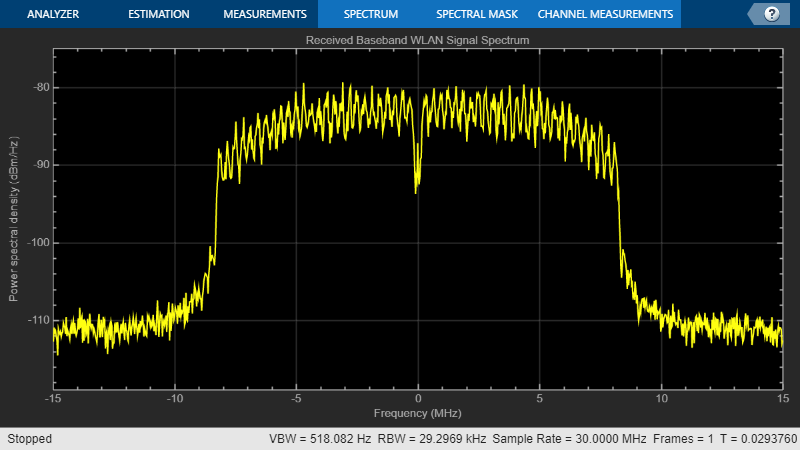


%Show the power spectral density of the received waveform.
spectrumScope.SampleRate = sampleRate*osf;
spectrumScope(rxWaveform);
release(spectrumScope);

## Receiver Processing


Packet-1 detected at index 2156


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-2 detected at index 10796


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-3 detected at index 19436


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-4 detected at index 28076


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-5 detected at index 36716


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-6 detected at index 45356


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-7 detected at index 53996


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-8 detected at index 62636


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-9 detected at index 71276


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-10 detected at index 79916


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-11 detected at index 88556


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-12 detected at index 97196


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-13 detected at index 105836


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-14 detected at index 114476


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-15 detected at index 123116


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-16 detected at index 131756


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-17 detected at index 140396


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-18 detected at index 149036


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-19 detected at index 157676


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-20 detected at index 166316


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-21 detected at index 174956


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-22 detected at index 183596


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-23 detected at index 192236


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-24 detected at index 200876


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-25 detected at index 209516


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-26 detected at index 218156


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-27 detected at index 226796


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-28 detected at index 235436


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-29 detected at index 244076


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-30 detected at index 252716


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-31 detected at index 261356


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-32 detected at index 269996


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-33 detected at index 278636


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-34 detected at index 287276


  Non-HT format detected


  L-SIG check pass 


  MAC FCS check pass



Packet-35 detected at index 295916


  Non-HT format detected


  L-SIG check pass 


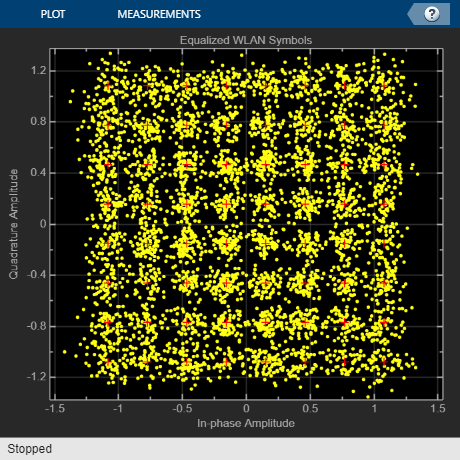

  MAC FCS check pass


%Design a rate conversion filter for resampling the waveform 
% to the nominal baseband rate for receiver processing 
% using the designMultirateFIR function.
aStop = 40; % Stopband attenuation
ofdmInfo = wlanNonHTOFDMInfo('NonHT-Data',nonHTcfg); % OFDM parameters
SCS = sampleRate/ofdmInfo.FFTLength; % Subcarrier spacing
txbw = max(abs(ofdmInfo.ActiveFrequencyIndices))*2*SCS; % Occupied bandwidth
[L,M] = rat(1/osf);
maxLM = max([L M]);
R = (sampleRate-txbw)/sampleRate;
TW = 2*R/maxLM; % Transition width
b = designMultirateFIR(L,M,TW,aStop);

%Resample the oversampled waveform back to 20 MHz for processing 
% using the dsp.FIRRateConverter System object and the filter designed above.
firrc = dsp.FIRRateConverter(L,M,b);
rxWaveform = firrc(rxWaveform);

% The wlanMPDUDecode function decodes the MPDU from the decoded PSDU bits 
% of each packet and outputs the MSDU as well as the recovered MAC frame
% configuration object wlanMACFrameConfig. The SequenceNumber property 
% in the recovered MAC frame configuration object can be used for ordering the MSDUs in the transmitted sequence.

%To display each packet's decoded L-SIG contents, the EVM measurements, and sequence number,
displayFlag = false;

%Set up required variables for receiver processing.
rxWaveformLen = size(rxWaveform,1);
searchOffset = 0; % Offset from start of the waveform in samples

%Get the required field indices within a PSDU.
ind = wlanFieldIndices(nonHTcfg);
Ns = ind.LSIG(2)-ind.LSIG(1)+1; % Number of samples in an OFDM symbol

% Minimum packet length is 10 OFDM symbols
lstfLen = double(ind.LSTF(2)); % Number of samples in L-STF
minPktLen = lstfLen*5;
pktInd = 1;
fineTimingOffset = [];
packetSeq = [];
rxBit = [];

% Perform EVM calculation
evmCalculator = comm.EVM(AveragingDimensions=[1 2 3]);
evmCalculator.MaximumEVMOutputPort = true;

%Use a while loop to process the received out-of-order packets.
while (searchOffset+minPktLen)<=rxWaveformLen
    % Packet detect
    pktOffset = wlanPacketDetect(rxWaveform,chanBW,searchOffset,0.5);

    % Adjust packet offset
    pktOffset = searchOffset+pktOffset;
    if isempty(pktOffset) || (pktOffset+double(ind.LSIG(2))>rxWaveformLen)
        if pktInd==1
            disp('** No packet detected **');
        end
        break;
    end

    % Extract non-HT fields and perform coarse frequency offset correction
    % to allow for reliable symbol timing
    nonHT = rxWaveform(pktOffset+(ind.LSTF(1):ind.LSIG(2)),:);
    coarseFreqOffset = wlanCoarseCFOEstimate(nonHT,chanBW);
    nonHT = frequencyOffset(nonHT,sampleRate,-coarseFreqOffset);

    % Symbol timing synchronization
    fineTimingOffset = wlanSymbolTimingEstimate(nonHT,chanBW);

    % Adjust packet offset
    pktOffset = pktOffset+fineTimingOffset;

    % Timing synchronization complete: Packet detected and synchronized
    % Extract the non-HT preamble field after synchronization and
    % perform frequency correction
    if (pktOffset<0) || ((pktOffset+minPktLen)>rxWaveformLen)
        searchOffset = pktOffset+1.5*lstfLen;
        continue;
    end
    fprintf('\nPacket-%d detected at index %d\n',pktInd,pktOffset+1);

    % Extract first 7 OFDM symbols worth of data for format detection and
    % L-SIG decoding
    nonHT = rxWaveform(pktOffset+(1:7*Ns),:);
    nonHT = frequencyOffset(nonHT,sampleRate,-coarseFreqOffset);

    % Perform fine frequency offset correction on the synchronized and
    % coarse corrected preamble fields
    lltf = nonHT(ind.LLTF(1):ind.LLTF(2),:);           % Extract L-LTF
    fineFreqOffset = wlanFineCFOEstimate(lltf,chanBW);
    nonHT = frequencyOffset(nonHT,sampleRate,-fineFreqOffset);
    cfoCorrection = coarseFreqOffset+fineFreqOffset; % Total CFO

    % Channel estimation using L-LTF
    lltf = nonHT(ind.LLTF(1):ind.LLTF(2),:);
    demodLLTF = wlanLLTFDemodulate(lltf,chanBW);
    chanEstLLTF = wlanLLTFChannelEstimate(demodLLTF,chanBW);

    % Noise estimation
    noiseVarNonHT = wlanLLTFNoiseEstimate(demodLLTF);

    % Packet format detection using the 3 OFDM symbols immediately
    % following the L-LTF
    format = wlanFormatDetect(nonHT(ind.LLTF(2)+(1:3*Ns),:), ...
        chanEstLLTF,noiseVarNonHT,chanBW);
    disp(['  ' format ' format detected']);
    if ~strcmp(format,'Non-HT')
        fprintf('  A format other than Non-HT has been detected\n');
        searchOffset = pktOffset+1.5*lstfLen;
        continue;
    end

    % Recover L-SIG field bits
    [recLSIGBits,failCheck] = wlanLSIGRecover( ...
        nonHT(ind.LSIG(1):ind.LSIG(2),:), ...
        chanEstLLTF,noiseVarNonHT,chanBW);

    if failCheck
        fprintf('  L-SIG check fail \n');
        searchOffset = pktOffset+1.5*lstfLen;
        continue;
    else
        fprintf('  L-SIG check pass \n');
    end

    % Retrieve packet parameters based on decoded L-SIG
    [lsigMCS,lsigLen,rxSamples] = helperInterpretLSIG(recLSIGBits,sampleRate);

    if (rxSamples+pktOffset)>length(rxWaveform)
        disp('** Not enough samples to decode packet **');
        break;
    end

    % Apply CFO correction to the entire packet
    rxWaveform(pktOffset+(1:rxSamples),:) = frequencyOffset(...
        rxWaveform(pktOffset+(1:rxSamples),:),sampleRate,-cfoCorrection);

    % Create a receive Non-HT config object
    rxNonHTcfg = wlanNonHTConfig;
    rxNonHTcfg.MCS = lsigMCS;
    rxNonHTcfg.PSDULength = lsigLen;

    % Get the data field indices within a PPDU
    indNonHTData = wlanFieldIndices(rxNonHTcfg,'NonHT-Data');

    % Recover PSDU bits using transmitted packet parameters and channel
    % estimates from L-LTF
    [rxPSDU,eqSym] = wlanNonHTDataRecover(rxWaveform(pktOffset+...
        (indNonHTData(1):indNonHTData(2)),:), ...
        chanEstLLTF,noiseVarNonHT,rxNonHTcfg);

    constellation(reshape(eqSym,[],1)); % Current constellation
    release(constellation);

    refSym = wlanClosestReferenceSymbol(eqSym,rxNonHTcfg);
    [evm.RMS,evm.Peak] = evmCalculator(refSym,eqSym);

    % Decode the MPDU and extract MSDU
    [cfgMACRx,msduList{pktInd},status] = wlanMPDUDecode(rxPSDU,rxNonHTcfg); %#ok<*SAGROW>

    if strcmp(status,'Success')
        disp('  MAC FCS check pass');

        % Store sequencing information
        packetSeq(pktInd) = cfgMACRx.SequenceNumber;

        % Convert MSDU to a binary data stream
        rxBit{pktInd} = int2bit(hex2dec(cell2mat(msduList{pktInd})),8,false);

    else % Decoding failed
        if strcmp(status,'FCSFailed')
            % FCS failed
            disp('  MAC FCS check fail');
        else
            % FCS passed but encountered other decoding failures
            disp('  MAC FCS check pass');
        end

        % Since there are no retransmissions modeled in this example, we
        % extract the image data (MSDU) and sequence number from the MPDU,
        % even though FCS check fails.

        % Remove header and FCS. Extract the MSDU.
        macHeaderBitsLength = 24*bitsPerOctet;
        fcsBitsLength = 4*bitsPerOctet;
        msduList{pktInd} = rxPSDU(macHeaderBitsLength+1:end-fcsBitsLength);

        % Extract and store sequence number
        sequenceNumStartIndex = 23*bitsPerOctet+1;
        sequenceNumEndIndex = 25*bitsPerOctet-4;
        conversionLength = sequenceNumEndIndex-sequenceNumStartIndex+1;
        packetSeq(pktInd) = bit2int(rxPSDU(sequenceNumStartIndex:sequenceNumEndIndex),conversionLength,false);

        % MSDU binary data stream
        rxBit{pktInd} = double(msduList{pktInd});
    end

    % Display decoded information
    if displayFlag
        fprintf('  Estimated CFO: %5.1f Hz\n\n',cfoCorrection); %#ok<*UNRCH> 

        disp('  Decoded L-SIG contents: ');
        fprintf('                            MCS: %d\n',lsigMCS);
        fprintf('                         Length: %d\n',lsigLen);
        fprintf('    Number of samples in packet: %d\n\n',rxSamples);

        fprintf('  EVM:\n');
        fprintf('    EVM peak: %0.3f%%  EVM RMS: %0.3f%%\n\n', ...
            evm.Peak,evm.RMS);

        fprintf('  Decoded MAC Sequence Control field contents:\n');
        fprintf('    Sequence number: %d\n\n',packetSeq(pktInd));
    end

    % Update search index
    searchOffset = pktOffset+double(indNonHTData(2));
    
    % Finish processing when a duplicate packet is detected. The
    % recovered data includes bits from duplicate frame
    % Remove the data bits from the duplicate frame
    if length(unique(packetSeq)) < length(packetSeq)
        rxBit = rxBit(1:length(unique(packetSeq)));
        packetSeq = packetSeq(1:length(unique(packetSeq)));
        break
    end

    pktInd = pktInd+1;
end



if strcmpi(channel,"OverTheAir")
    release(sdrTransmitter);
    release(sdrReceiver);
end


## Reconstruct Image

  
Bit Error Rate (BER):


          Bit Error Rate (BER) = 0.00000


          Number of bit errors = 0


    Number of transmitted bits = 626688




Constructing image from received data.


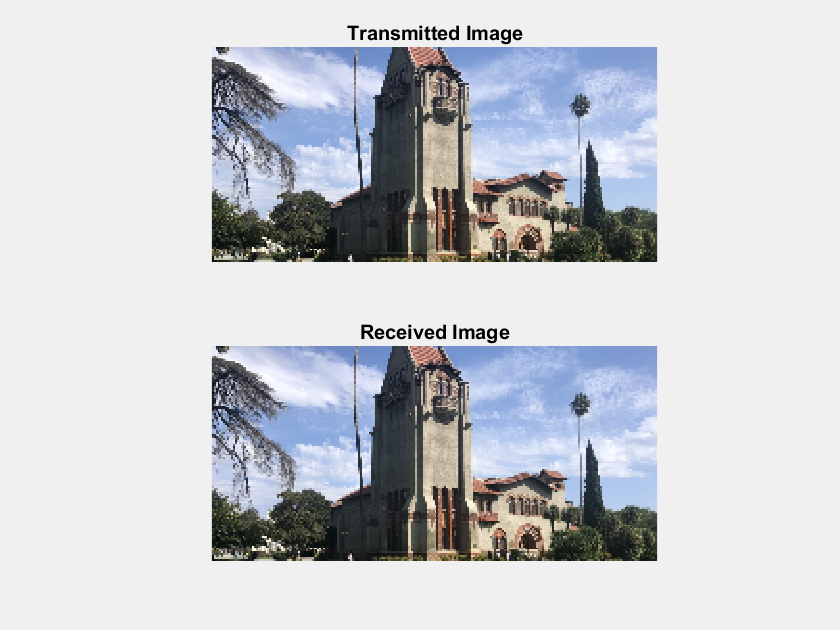

if ~(isempty(fineTimingOffset) || isempty(pktOffset))

    % Convert decoded bits from cell array to column vector
    rxData = cat(1,rxBit{:});
    % Remove any extra bits
    rxData = rxData(1:end-(mod(length(rxData),msduLength*8)));
    % Reshape such that each column length has bits equal to msduLength*8
    rxData = reshape(rxData,msduLength*8,[]);

    % Remove duplicate packets if any. Duplicate packets are located at the
    % end of rxData
    if length(packetSeq)>numMSDUs
        numDupPackets = size(rxData,2)-numMSDUs;
        rxData = rxData(:,1:end-numDupPackets);
    end

    % Initialize variables for while loop
    startSeq = [];
    i=-1;

    % Only execute this if one of the packet sequence values have been decoded
    % accurately
    if any(packetSeq<numMSDUs)
        while isempty(startSeq)
            % This searches for a known packetSeq value
            i = i + 1;
            startSeq = find(packetSeq==i);
        end
        % Circularly shift data so that received packets are in order for image reconstruction. It
        % is assumed that all packets following the starting packet are received in
        % order as this is how the image is transmitted.
        rxData = circshift(rxData,[0 -(startSeq(1)-i-1)]); % Order MAC fragments

        % Perform bit error rate (BER) calculation on reordered data
        bitErrorRate = comm.ErrorRate;
        err = bitErrorRate(double(rxData(:)), ...
            txDataBits(1:length(reshape(rxData,[],1))));
        fprintf('  \nBit Error Rate (BER):\n');
        fprintf('          Bit Error Rate (BER) = %0.5f\n',err(1));
        fprintf('          Number of bit errors = %d\n',err(2));
        fprintf('    Number of transmitted bits = %d\n\n',length(txDataBits));
    end

    decData = bit2int(reshape(rxData(:),8,[]),8,false)';

    % Append NaNs to fill any missing image data
    if length(decData)<length(txImage)
        numMissingData = length(txImage)-length(decData);
        decData = [decData;NaN(numMissingData,1)];
    else
        decData = decData(1:length(txImage));
    end

    % Recreate image from received data
    fprintf('\nConstructing image from received data.\n');
    receivedImage = uint8(reshape(decData,imsize));
    % Plot received image
    if exist('imFig','var') && ishandle(imFig) % If Tx figure is open
        figure(imFig); subplot(212);
    else
        figure; subplot(212);
    end
    imshow(receivedImage);
    title(sprintf('Received Image'));
end